AAE 334L LAB 5 MATLAB CODE 

AUTHOR: TOMOKI KOIKE 

clear all; close all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE334LAB\matlab\outputs\lab5';
set(groot, 'defaulttextinterpreter',"latex");
set(groot, 'defaultAxesTickLabelInterpreter',"latex");
set(groot, 'defaultLegendInterpreter',"latex");

% Importing xlsx data files 
press_measur  = xlsread("inputs\lab5\lab5_example_data.xlsx",'Pressure Measurements');
thrust_measur = xlsread("inputs\lab5\lab5_example_data.xlsx",'Thrust Measurements');

% Assigning variables to the obtained data 
% Sheet 1 - pressure measurements 
reservoir_p1 = press_measur(:,1);      % the reservoir pressure values [psia] for the first sheet
tap_p      = press_measur(:,2:end);    % the gauge pressure values from the pressure taps [psi]
% Sheet 2 - thrust measurements 
reservoir_p2 = thrust_measur(:,1);     % the reservoir pressure values [psia] for the second sheet
thrust_vals  = thrust_measur(:,2);     % the thrust values for each pressure value [lbf]

% Defining constants 
rho_0  = 1.225;     % stagnation density [kg/m3]
p_ref  = 14.7;      % reference pressure P_ref [psia]
R      = 287.05;    % gas constant [J/kg/K]
gamma  = 1.4;       % specific heat ratio 

% Nozzle area
A1     = pi*inch2m(0.725/2)^2;  % area at pressure tap 1 [m^2]
A_star = pi*inch2m(0.46/2)^2;   % area at throat [m2]
A2     = A_star;
A3     = pi*inch2m(0.50/2)^2;   % area at pressure tap 3 [m^2]
A4     = pi*inch2m(0.55/2)^2;   % area at pressure tap 4 [m^2]
A5     = pi*inch2m(0.58/2)^2;   % area at pressure tap 5 [m^2]
A6     = pi*inch2m(0.59/2)^2;   % area at pressure tap 6 [m^2]
A7     = pi*inch2m(0.60/2)^2;   % area at pressure tap 7 [m^2]
A8     = pi*inch2m(0.60/2)^2;   % area at pressure tap 8 [m^2]
As     = [A1, A2, A3, A4, A5, A6, A7, A8];

% * (psia) = (psi) - (psig) >> use this relation  
% Calculating the gauge pressure for the reservoir pressure and the
% pressure tap pressures 
p1 = psi2Pa(tap_p + p_ref);  % [Pa]

2.1 (a) 

% Convert to mertic pressures for convenience 
reservoir_p1_Pa = psi2Pa(reservoir_p1);  % [Pa]
reservoir_p2_Pa = psi2Pa(reservoir_p2);  % [Pa]

% Stagnation pressures for each condition
T0_1 = reservoir_p1_Pa/rho_0/R;
% Stagnation sound velocity for each condition
a0_1 = sqrt(gamma*R*T0_1);
% Mass flows for each conditions 
m_dot = 0.8103*reservoir_p1_Pa./a0_1*A_star;

2.1 (b)

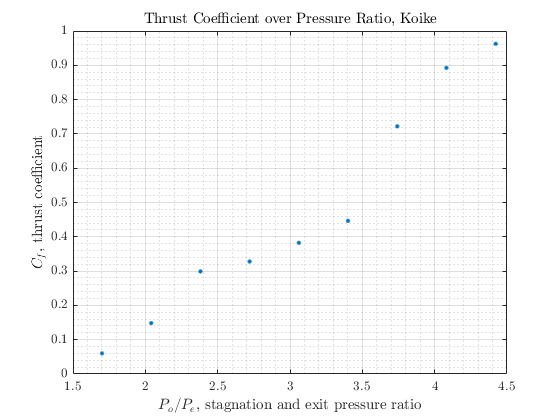

% Calculating the thrust coefficients 
thrust_vals_N = lbf2Newton(thrust_vals);  % converting from lbf to N
Cf = thrust_vals_N./A_star./reservoir_p2_Pa;

% Plotting
fig1 = figure("Renderer","painters");
    plot(reservoir_p2/p_ref, Cf, '.',"MarkerSize",9)
    title("Thrust Coefficient over Pressure Ratio, Koike")
    xlabel('$P_o$/$P_e$, stagnation and exit pressure ratio')
    ylabel('$C_f$, thrust coefficient')
    grid on; grid minor; box on;
saveas(fig1,fullfile(fdir,'thrust_coefficients.png'));

2.2 

% Theoretical Mach numbers, static pressures, & static temperatures 
Ms = zeros([1 8]);
Ps = zeros([6 8]);
Ts = zeros([6 8]);
for i = 1:8
    M = machNumber_from_area(As(i),A_star,gamma);
    if i == 1
        Ms(i) = M(M<1);
    elseif i >= 3
        Ms(i) = M(M>1);
    else
        Ms(i) = M;
    end
    for n = 1:6
        Ps(n,i) = p_from_M_and_gamma(reservoir_p1_Pa(n),Ms(i),gamma,"static");
        Ts(n,i) = T_from_M_and_gamma(T0_1(n),Ms(i),gamma,"static");
    end
end

% Convert pressure from Pa to psig
Ps_psig = Pa2psi(Ps) - p_ref;

% Experimental Mach numbers 
Ms_exp = zeros([6 8]);
for i = 1:6
    Ms_exp(i,1:8) = machNumber_from_p(reservoir_p1_Pa(i),p1(i,1:8),gamma);
end

% Experimental Temperatures 
Ts_exp = zeros([6 8]);
for i = 1:6
    Ts_exp(i,1:8) = Tstatic_from_isentropic_relations(T0_1(i),reservoir_p1_Pa(i),p1(i,1:8),gamma);
end

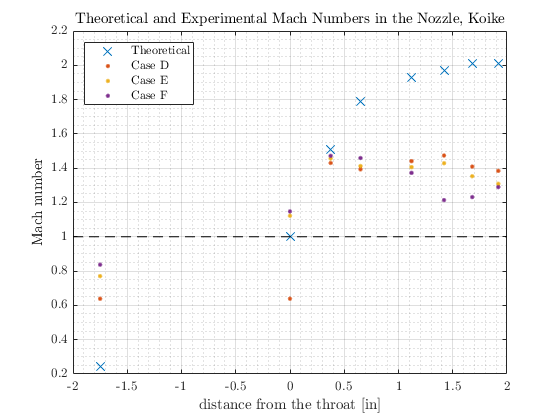

% Plotting
dist = [-1.75 0 0.375 0.65 1.12 1.42 1.68 1.92];  % Distance from the throat in the nozzle [in]
% Mach numbers 
fig2 = figure("Renderer","painters");
    plot(dist,Ms,'x',"MarkerSize",9)
    title("Theoretical and Experimental Mach Numbers in the Nozzle, Koike")
    xlabel('distance from the throat [in]')
    ylabel('Mach number')
    hold on 
    plot(dist,Ms_exp(4,1:end),'.','MarkerSize',9)
    plot(dist,Ms_exp(5,1:end),'.','MarkerSize',9)
    plot(dist,Ms_exp(6,1:end),'.','MarkerSize',9)
    plot(linspace(-2,2,8),ones([1 8]),'--k')
    hold off
    grid on; grid minor; box on;
    legend('Theoretical','Case D','Case E','Case F','Location',"northwest")
saveas(fig2,fullfile(fdir,'mach_num.png'))

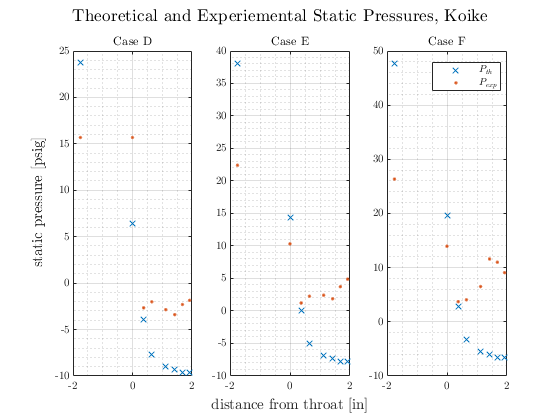

% Static pressures
fig3 = figure("Renderer","painters");
    sgtitle('Theoretical and Experiemental Static Pressures, Koike')
    subplot(1,3,1)
        plot(dist,Ps_psig(4,1:end),'x')
        title('Case D')
        hold on
        plot(dist,tap_p(4,1:end),'.')
        hold off
        grid on; grid minor; box on;
    subplot(1,3,2)
        plot(dist,Ps_psig(5,1:end),'x')
        title('Case E')
        hold on
        plot(dist,tap_p(5,1:end),'.')
        hold off
        grid on; grid minor; box on;
    subplot(1,3,3)
        plot(dist,Ps_psig(6,1:end),'x')
        title('Case F')
        hold on
        plot(dist,tap_p(6,1:end),'.')
        hold off
        legend("$P_{th}$",'$P_{exp}$')
        grid on; grid minor; box on;
     % Give common xlabel, ylabel and title to your figure
    han=axes(fig3,'visible','off'); 
    han.Title.Visible='on';
    han.XLabel.Visible='on';
    han.YLabel.Visible='on';
    ylabel(han,'static pressure [psig]');
    xlabel(han,'distance from throat [in]');
saveas(fig3,fullfile(fdir,'static_pressure_D-E-F.png'))

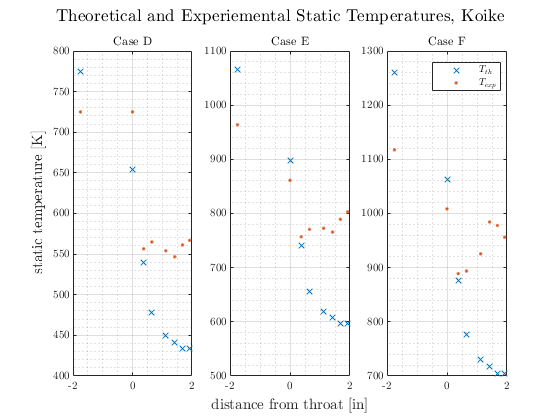

% Static temperatures
fig4 = figure("Renderer","painters");
    sgtitle('Theoretical and Experiemental Static Temperatures, Koike')
    subplot(1,3,1)
        plot(dist,Ts(4,1:end),'x')
        title('Case D')
        hold on
        plot(dist,Ts_exp(4,1:end),'.')
        hold off
        grid on; grid minor; box on;
    subplot(1,3,2)
        plot(dist,Ts(5,1:end),'x')
        title('Case E')
        hold on
        plot(dist,Ts_exp(5,1:end),'.')
        hold off
        grid on; grid minor; box on;
    subplot(1,3,3)
        plot(dist,Ts(6,1:end),'x')
        title('Case F')
        hold on
        plot(dist,Ts_exp(6,1:end),'.')
        hold off
        legend("$T_{th}$",'$T_{exp}$')
        grid on; grid minor; box on;
     % Give common xlabel, ylabel and title to your figure
    han=axes(fig4,'visible','off'); 
    han.Title.Visible='on';
    han.XLabel.Visible='on';
    han.YLabel.Visible='on';
    ylabel(han,'static temperature [K]');
    xlabel(han,'distance from throat [in]');
saveas(fig4,fullfile(fdir,'static_temperature_D-E-F.png'))

2.3

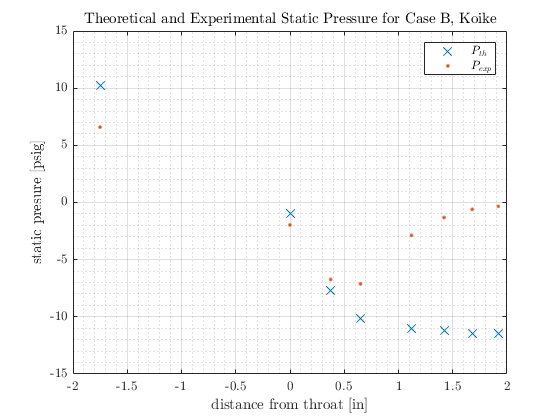

fig5 = figure("Renderer","painters");
    plot(dist,Ps_psig(2,1:end),'x',"MarkerSize",9)
    title('Theoretical and Experimental Static Pressure for Case B, Koike')
    xlabel('distance from throat [in]')
    ylabel('static presure [psig]')
    hold on
    plot(dist,tap_p(2,1:end),'.',"MarkerSize",7)
    hold off
    grid on; grid minor; box on;
    legend("$P_{th}$",'$P_{exp}$')
saveas(fig5,fullfile(fdir,'static_pressure_B.png'))

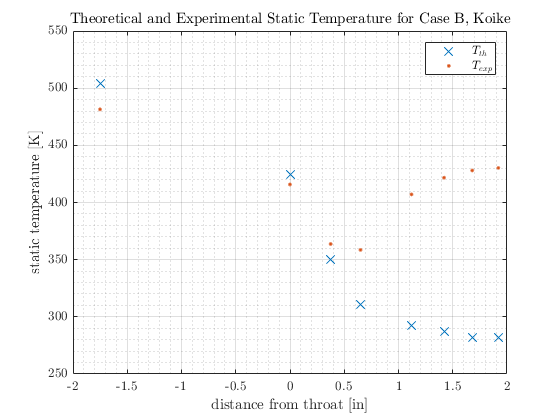

fig6 = figure("Renderer","painters");
    plot(dist,Ts(2,1:end),'x',"MarkerSize",9)
    title('Theoretical and Experimental Static Temperature for Case B, Koike')
    xlabel('distance from throat [in]')
    ylabel('static temperature [K]')
    hold on
    plot(dist,Ts_exp(2,1:end),'.',"MarkerSize",7)
    hold off
    grid on; grid minor; box on;
    legend("$T_{th}$",'$T_{exp}$')
saveas(fig6,fullfile(fdir,'static_temperature_B.png'))

FUNCTION

function F = lbf2Newton(f)
    F = f*4.44822;
end

function P = Pa2psi(p)
    % This function converts the units of psi to Pa
    P = p / 6894.76;
end

function M = machNumber_from_area(A,At,gamma)
    %{
      function to calculate the Mach number from the area ratio
    %}
    syms M
    assume(M,["real","positive"]);
    a1 = 2/(gamma + 1);               % intermediate var 1
    a2 = (1 + (gamma - 1)/2*M^2);     % intermediate var 2
    a3 = (gamma + 1)/(gamma - 1);     % intermediate var 3
    eqn = (A/At)^2 == 1/M^2*(a1*a2)^(a3);
    M = double(solve(eqn,M));
end

function M = machNumber_from_p(P0,P,gamma)
    %{ 
      Function that computes the mach number from the stagnation and static
      pressures 
    %}
    a1 = 2/(gamma - 1);               % intermediate var 1
    a2 = (P0./P).^((gamma - 1)/gamma);  % intermediate var 2
    M = sqrt(a1.*(a2 - 1));
end

function T = Tstatic_from_isentropic_relations(T0,P0,P,gamma)
    T = T0.*(P0./P).^((1 - gamma)/gamma);
end